# FFT For Image Analysis

Gati Aher

SP2021: Quantitative Engineering Analysis

## Explore Image Fourier Transforms

sine plots

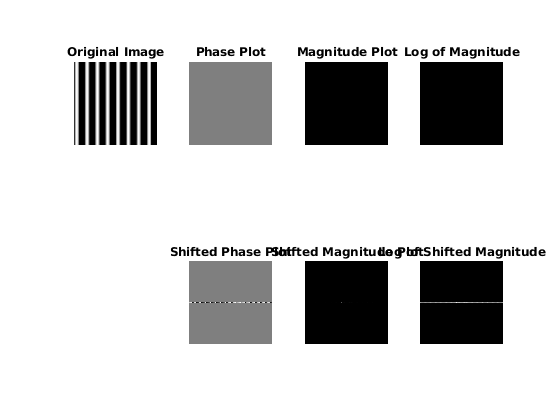

explore_fft(imread("img/vertical_sine_img_f8.png"));

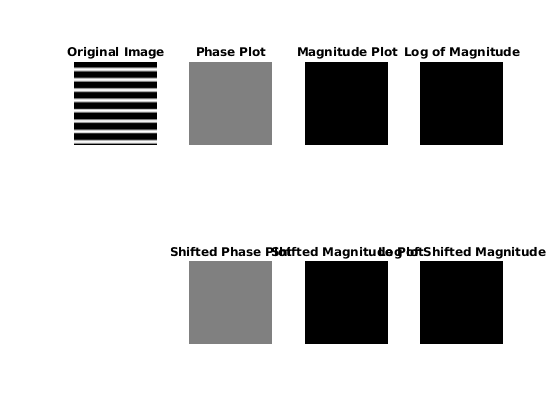

explore_fft(imread("img/horizontal_sine_img_f8.png"));

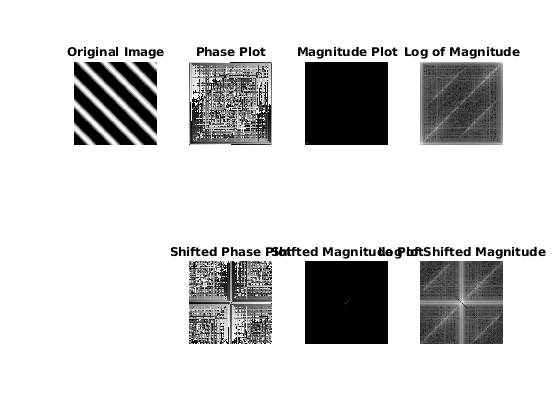

explore_fft(imread("img/diagonal_sine_img_scaled_f8.png"));

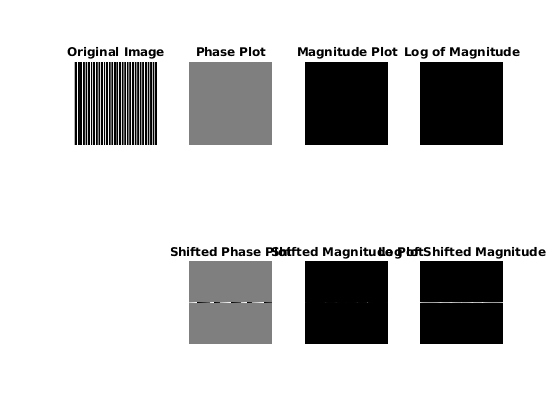


explore_fft(imread("img/vertical_sine_img_f32.png"));

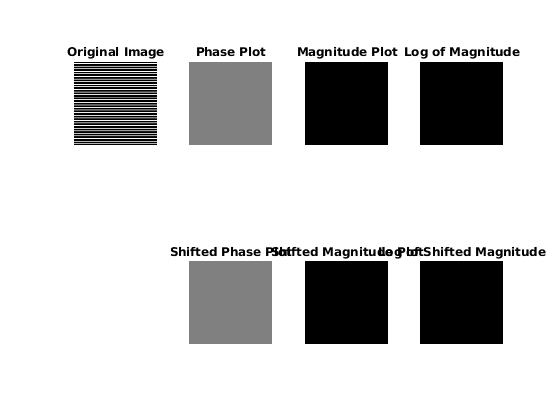

explore_fft(imread("img/horizontal_sine_img_f32.png"));

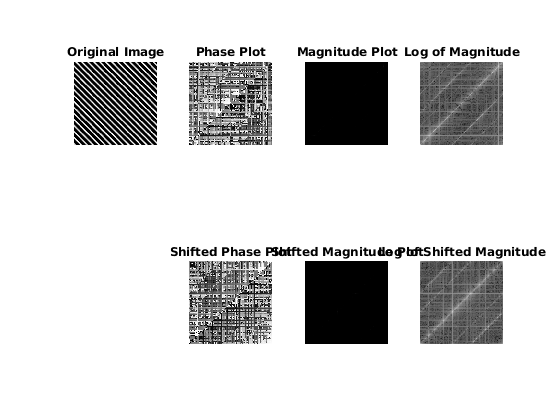

explore_fft(imread("img/diagonal_sine_img_scaled_f32.png"));

rectangles

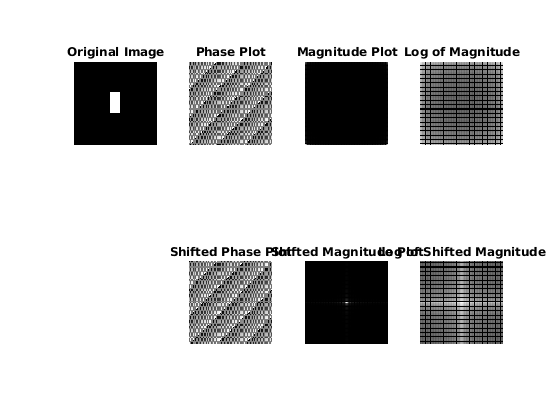

explore_fft(imread("img/rect_32x64px.png"));

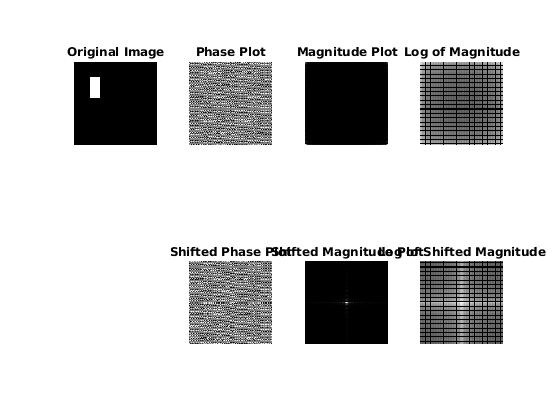

explore_fft(imread("img/rect_32x64px_offset_by_50.png"));

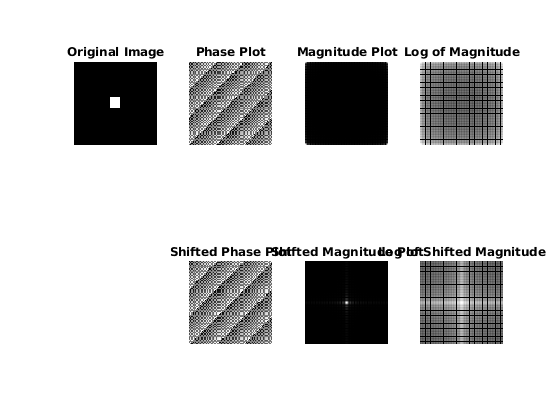

explore_fft(imread("img/square_32px.png"));

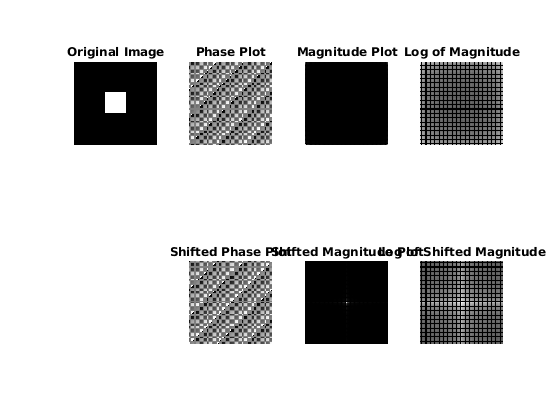

explore_fft(imread("img/square_64px.png"));

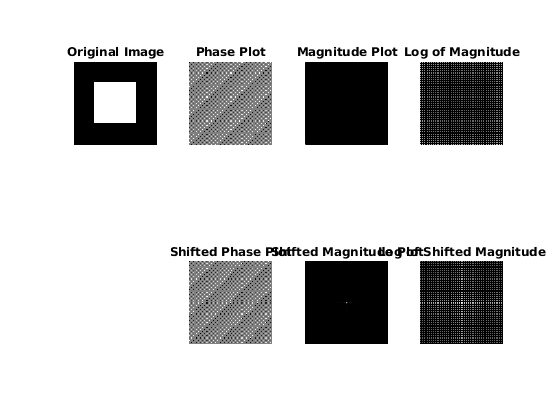

explore_fft(imread("img/square_128px.png"));

natural patterns

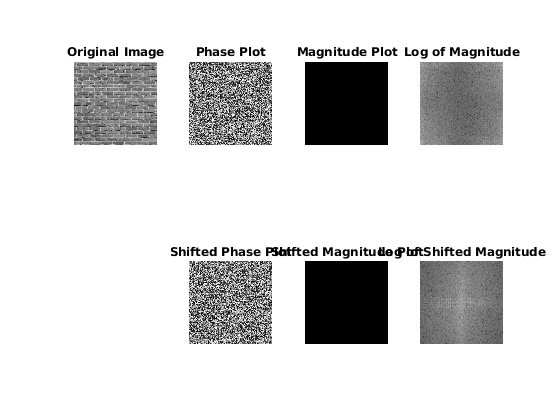

explore_fft(imread("img/brick.png"));

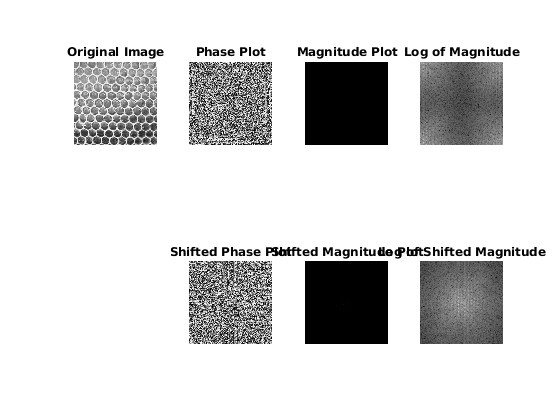

explore_fft(imread("img/honeycomb.png"));

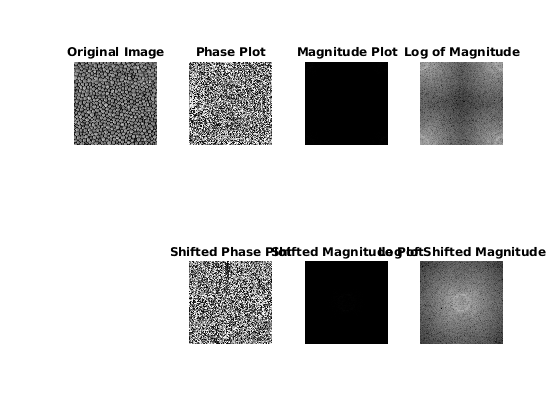

explore_fft(imread("img/mustard_seeds.png"));

complex images

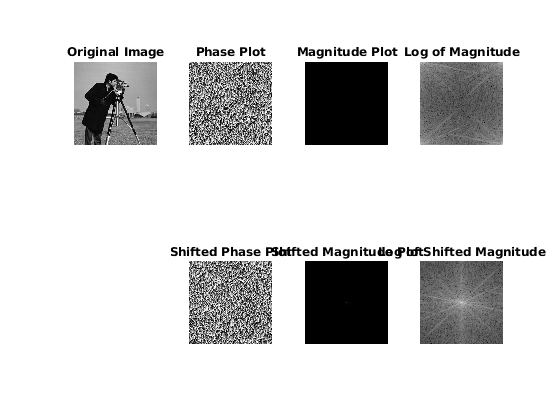

explore_fft(imread("img/cameraman.png"));

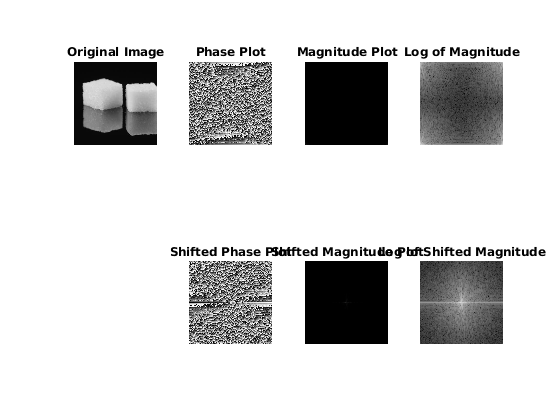

explore_fft(imread("img/sugar_cube.png"));

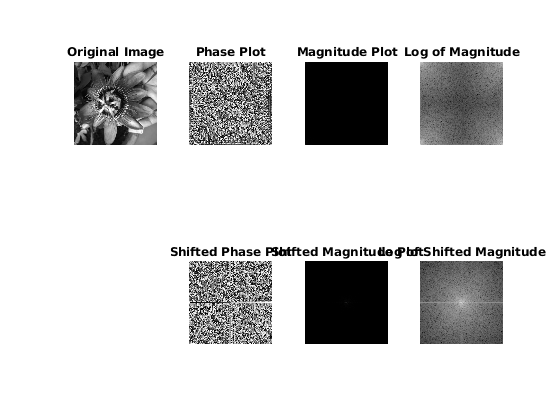

explore_fft(imread("img/flower.png"));

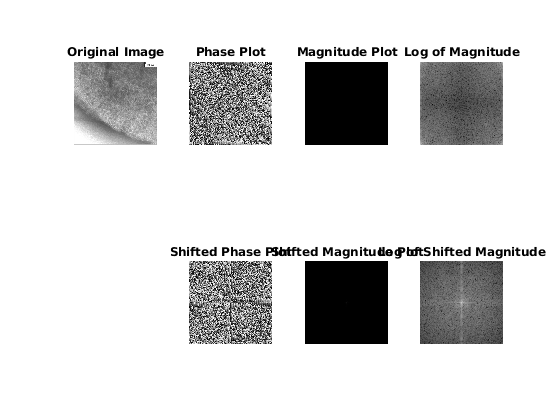


explore_fft(imread("img/bacteria_slayer.png"));

other

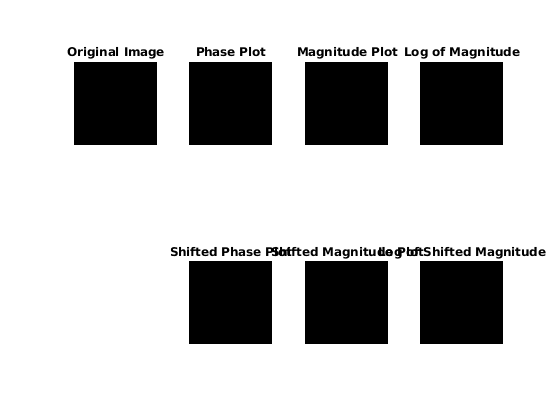

explore_fft("img/blank.png");

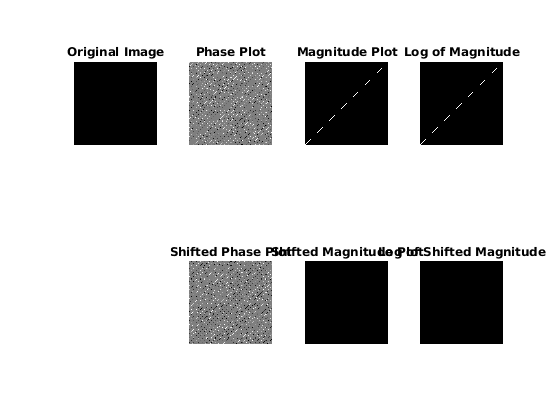

explore_fft("img/diagonal_lines.png");

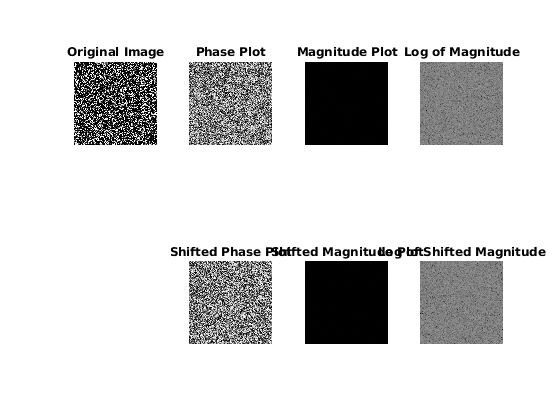

explore_fft("img/noise.png");

## Windowing

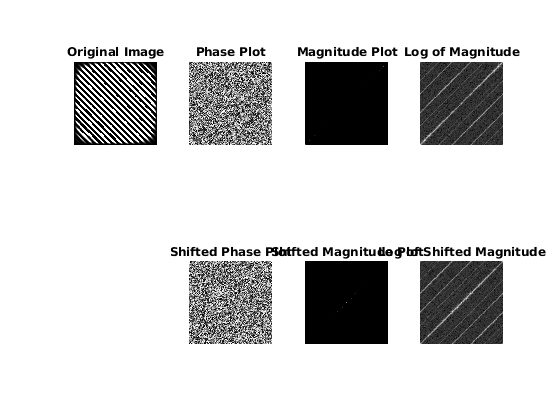

img = imread("img/diagonal_sine_img_scaled_f32.png");
w = hann(N, 'periodic');
explore_fft(double(img) .* (w.*w'));

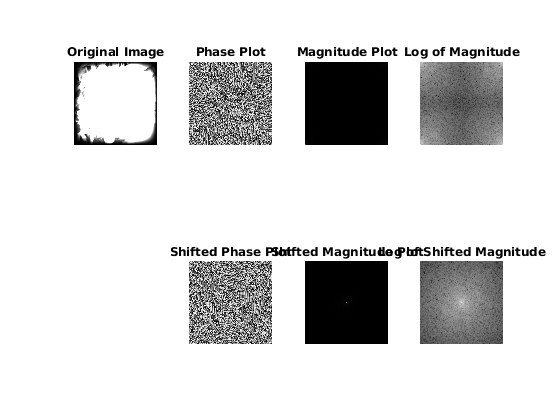

img = imread("img/flower.png");
w = hann(N, 'periodic');
explore_fft(double(img) .* (w.*w'));

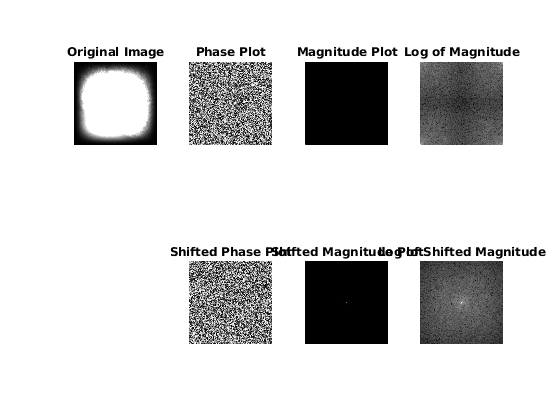


img = imread("img/bacteria_slayer.png");
w = hann(N, 'periodic') .* 0.25;
explore_fft(double(img) .* (w.*w'));

## Check Filters

Sanity check that filters work as expected:

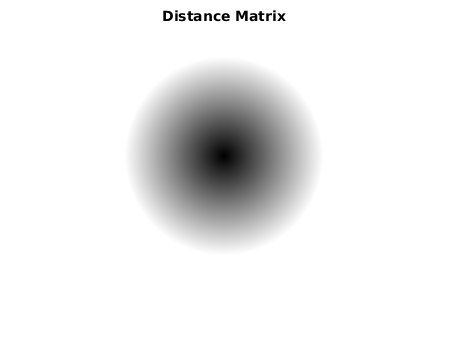

N = 256;
figure, imshow(distance_mat(zeros(N, N)), [0, 100]), title("Distance Matrix");

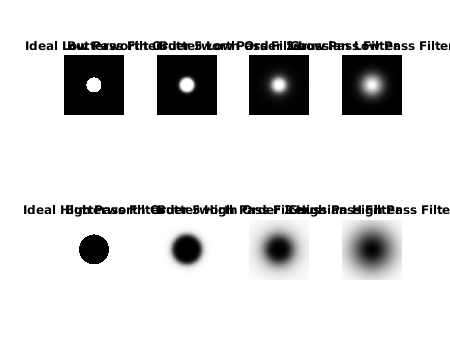

idf = idealFilterLP(N/4, zeros(N, N));
bwf5 = butterworthLP(N/4, zeros(N, N), 5);
bwf2 = butterworthLP(N/4, zeros(N, N), 2);
gf = gaussianLP(N/4, zeros(N, N));

subplot(2, 4, 1), imshow(idf, []), title("Ideal Low Pass Filter");
subplot(2, 4, 2), imshow(bwf5, []), title("Butterworth Order 5 Low Pass Filter");
subplot(2, 4, 3), imshow(bwf2, []), title("Butterworth Order 2 Low Pass Filter");
subplot(2, 4, 4), imshow(gf, []), title("Gaussian Low Pass Filter");

subplot(2, 4, 5), imshow(idealFilterHP(N/4, zeros(N, N)), [0, 1]), title("Ideal High Pass Filter");
subplot(2, 4, 6), imshow(butterworthHP(N/4, zeros(N, N), 5), [0, 1]), title("Butterworth Order 5 High Pass Filter");
subplot(2, 4, 7), imshow(butterworthHP(N/4, zeros(N, N), 2), [0, 1]), title("Butterworth Order 2 High Pass Filter");
subplot(2, 4, 8), imshow(gaussianHP(N/4, zeros(N, N)), [0, 1]), title("Gaussian High Pass Filter");

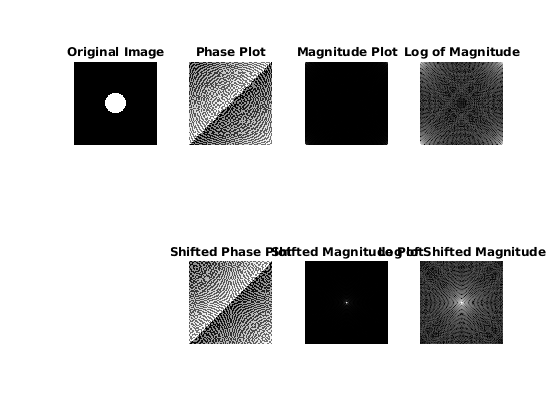

% calculate fft phase and magnitude for each filter
explore_fft(idf);

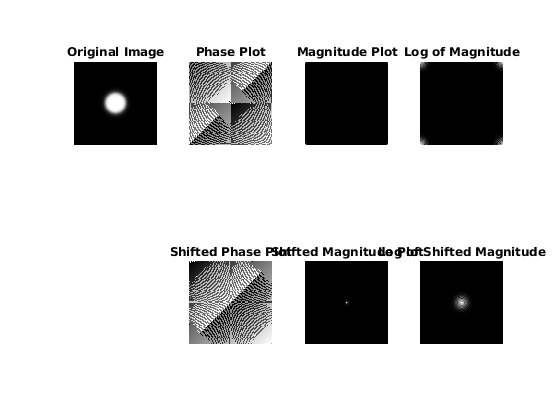

explore_fft(bwf5);

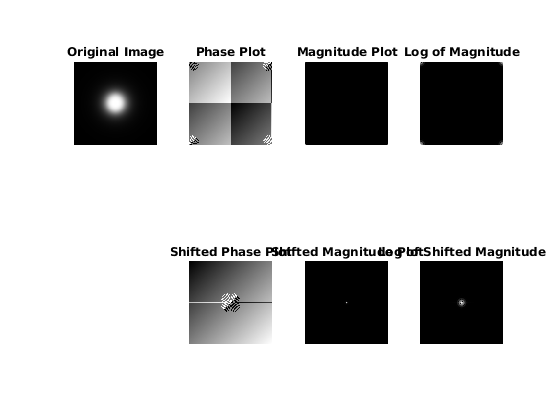

explore_fft(bwf2);

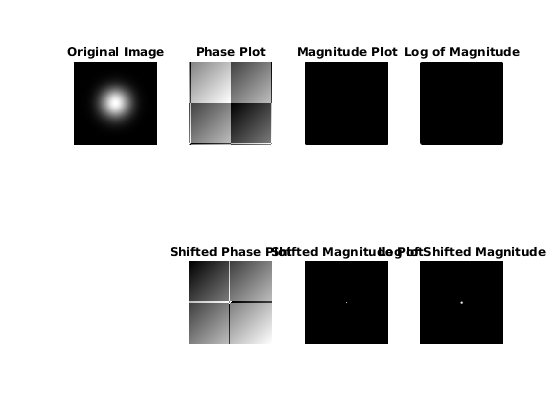

explore_fft(gf);

## Try Filtering

img = imread("img/square_128px.png");
N = size(img, 1);

explore_fft(img);

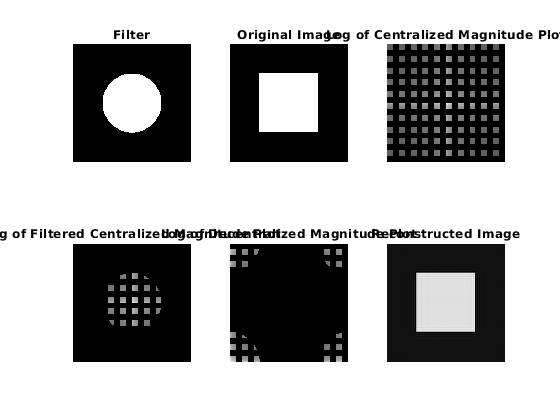

explore_filter_fft(img, idealFilterLP(N/4, zeros(N, N)));

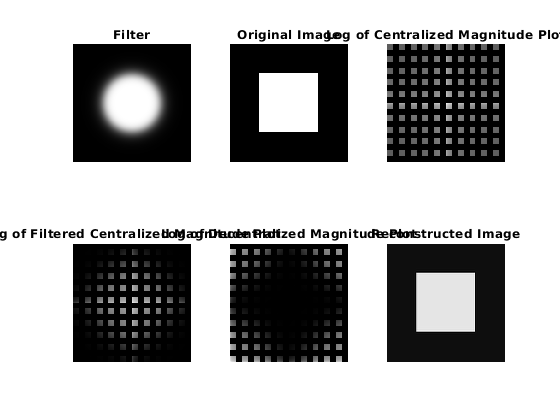

explore_filter_fft(img, butterworthLP(N/4, zeros(N, N), 5));

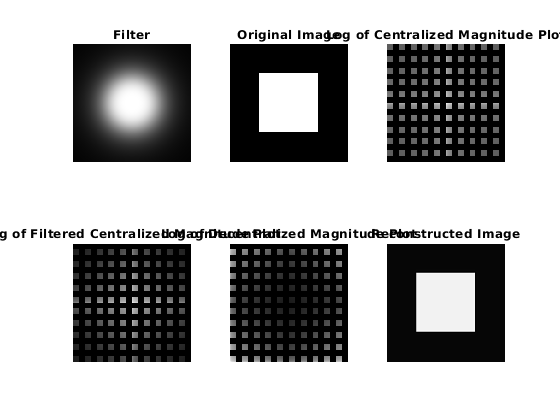

explore_filter_fft(img, butterworthLP(N/4, zeros(N, N), 2));

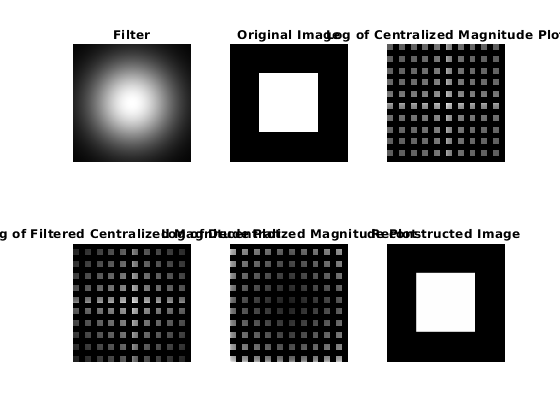

explore_filter_fft(img, gaussianLP(N/4, zeros(N, N)));


figure
subplot(2, 5, 1), imshow(img), title("Original Image");

subplot(2, 5, 2), imshow(get_filter_fft(img, idealFilterLP(N/4, zeros(N, N))), []), title("Recon. Ideal LP size N/4");

subplot(2, 5, 3), imshow(get_filter_fft(img, butterworthLP(N/4, zeros(N, N), 5)), []), title("Recon. Butterworth 5 LP size N/4");

subplot(2, 5, 4), imshow(get_filter_fft(img, butterworthLP(N/4, zeros(N, N), 2)), []), title("Recon. Butterworth 2 LP size N/4");

subplot(2, 5, 5), imshow(get_filter_fft(img, gaussianLP(N/4, zeros(N, N))), []), title("Recon. Gaussian LP size N/4");


subplot(2, 5, 7), imshow(get_filter_fft(img, idealFilterLP(N/32, zeros(N, N))), []), title("Recon. Ideal LP size N/32");

subplot(2, 5, 8), imshow(get_filter_fft(img, butterworthLP(N/32, zeros(N, N), 5)), []), title("Recon. Butterworth 5 LP size N/32");

subplot(2, 5, 9), imshow(get_filter_fft(img, butterworthLP(N/32, zeros(N, N), 2)), []), title("Recon. Butterworth 2 LP size N/32");

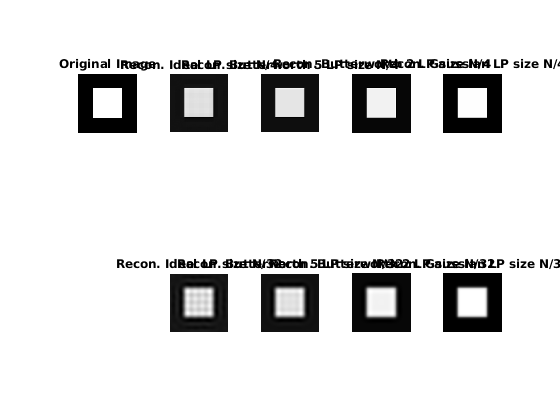

subplot(2, 5, 10), imshow(get_filter_fft(img, gaussianLP(N/32, zeros(N, N))), []), title("Recon. Gaussian LP size N/32");



figure
subplot(2, 5, 1), imshow(img), title("Original Image");

subplot(2, 5, 2), imshow(get_filter_fft(img, idealFilterHP(N/4, zeros(N, N))), []), title("Recon. Ideal HP size N/4");

subplot(2, 5, 3), imshow(get_filter_fft(img, butterworthHP(N/4, zeros(N, N), 5)), []), title("Recon. Butterworth 5 HP size N/4");

subplot(2, 5, 4), imshow(get_filter_fft(img, butterworthHP(N/4, zeros(N, N), 2)), []), title("Recon. Butterworth 2 HP size N/4");

subplot(2, 5, 5), imshow(get_filter_fft(img, gaussianHP(N/4, zeros(N, N))), []), title("Recon. Gaussian HP size N/4");


subplot(2, 5, 7), imshow(get_filter_fft(img, idealFilterHP(N/32, zeros(N, N))), []), title("Recon. Ideal HP size N/32");

subplot(2, 5, 8), imshow(get_filter_fft(img, butterworthHP(N/32, zeros(N, N), 5)), []), title("Recon. Butterworth 5 HP size N/32");

subplot(2, 5, 9), imshow(get_filter_fft(img, butterworthHP(N/32, zeros(N, N), 2)), []), title("Recon. Butterworth 2 HP size N/32");

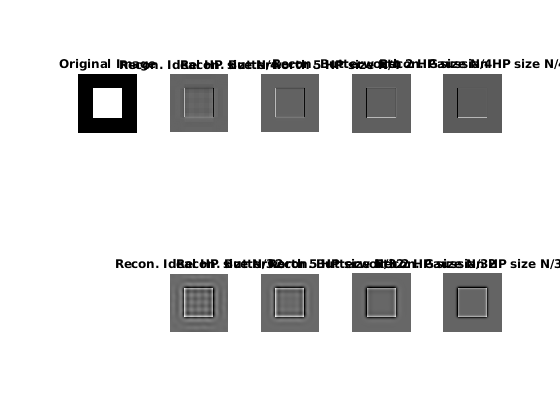

subplot(2, 5, 10), imshow(get_filter_fft(img, gaussianHP(N/32, zeros(N, N))), []), title("Recon. Gaussian HP size N/32");

## FFT Function:

function f = explore_fft(img)
    img_fft = fft2(double(img));
    img_phase = angle(img_fft);
    img_mag = abs(img_fft);
    img_mag_log = log(1 + img_mag);
    
    img_fftshift = fftshift(img_fft);
    img_phase_shift = angle(img_fftshift);
    img_mag_shift = abs(img_fftshift);
    img_mag_shift_log = log(1 + img_mag_shift);
    
    f = figure;
  
    subplot(2, 4, 1), imshow(img), title("Original Image");
    subplot(2, 4, 2), imshow(img_phase, []), title("Phase Plot");
    subplot(2, 4, 3), imshow(img_mag, []), title("Magnitude Plot");
    subplot(2, 4, 4), imshow(img_mag_log, []), title("Log of Magnitude");
    
    subplot(2, 4, 6), imshow(img_phase_shift, []), title("Shifted Phase Plot");
    subplot(2, 4, 7), imshow(img_mag_shift, []), title("Shifted Magnitude Plot");
    subplot(2, 4, 8), imshow(img_mag_shift_log, []), title("Log of Shifted Magnitude");    
end

## FFT + Filter Function

function f = explore_filter_fft(img, filter)
    img_fftshift = fftshift(fft2(double(img)));
    img_filter_fft = img_fftshift .* double(filter);   
    img_filter_decentralize = ifftshift(img_filter_fft);
    img_filter_reconstructed = ifft2(img_filter_decentralize);
    
    f = figure;
  
    subplot(2, 3, 1), imshow(filter), title("Filter");
    subplot(2, 3, 2), imshow(img), title("Original Image");
    subplot(2, 3, 3), imshow(log(1 + abs(img_fftshift)), []), title("Log of Centralized Magnitude Plot");
    subplot(2, 3, 4), imshow(log(1 + abs(img_filter_fft)), []), title("Log of Filtered Centralized Magnitude Plot");
    subplot(2, 3, 5), imshow(log(1 + abs(img_filter_decentralize)), []), title("Log of Decentralized Magnitude Plot");
    subplot(2, 3, 6), imshow(img_filter_reconstructed, []), title("Reconstructed Image");    
end

function img_filter_reconstructed = get_filter_fft(img, filter)
    img_fftshift = fftshift(fft2(double(img)));
    img_filter_fft = img_fftshift .* double(filter);   
    img_filter_decentralize = ifftshift(img_filter_fft);
    img_filter_reconstructed = ifft2(img_filter_decentralize);
end

## Filter Functions:

function distMat = distance_mat(img)
    % get center of image
    [nx, ny] = size(img);
    x = linspace(-nx/2, nx/2, nx);
    y = linspace(-ny/2, ny/2, ny);
    % calculate distance matrix
    [X, Y] = meshgrid(x, y);
    distMat = sqrt((X.^2)+(Y.^2));
end

function base = idealFilterLP(cutoff, img)
    % get distance matrix for image
    distMat = distance_mat(img);
    % perform logical mask
    mask = distMat < cutoff;
    % everything below cutoff is True (1)
    % everything above cutoff is False (0)
    base = mask;
end

function base = idealFilterHP(cutoff, img)
    % get distance matrix for image
    distMat = distance_mat(img);
    % perform logical mask
    mask = distMat > cutoff;
    % everything below cutoff is False (0)
    % everything above cutoff is True (1)
    base = mask;
end

function base = butterworthLP(cutoff, img, order)
    % get distance matrix for image
    distMat = distance_mat(img);
    % get butterworth values
    base = 1./(1+(distMat./cutoff).^(2*order));
end

function base = butterworthHP(cutoff, img, order)
    % high-pass is just inverted low-pass
    base = 1 - butterworthLP(cutoff, img, order);
end

function base = gaussianLP(cutoff, img)
    % get distance matrix for image
    distMat = distance_mat(img);
    % get butterworth values
%     base = expm(((-1 .* (distMat.^2))./(2*(cutoff^2))));
    base = exp(-1 .* (distMat.^2)./(2*(cutoff^2)));
end

function base = gaussianHP(cutoff, img)
    % high-pass is just inverted low-pass
    base = 1 - gaussianLP(cutoff, img);
end